% Set the parameters
duration = 2;       % Duration in seconds
frequency = 300;    % Frequency in Hz
fs = 1e3;  % Sampling rate in Hz

t = 0:1/fs:duration;

x1 = sin(2*pi*300*t);
x2 = sin(2*pi*210*t);

rng default
wgnNoise = 0.4*randn(size(t));

x = x1+x2+wgnNoise;

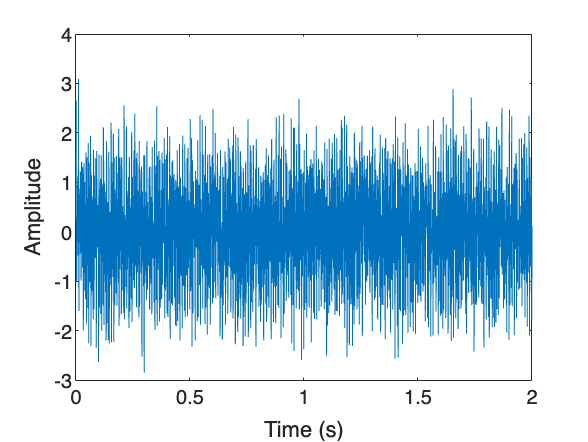

% Plot the waveform
% plot(t(1:100), x(1:100));
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');

sound(x,fs,16);

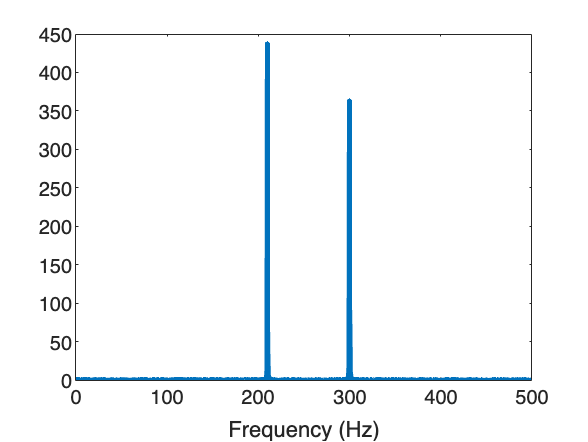

% power spectrum
dt = 1/fs;
n = length(t);
xhat = fft(x, n);
PSD = xhat.*conj(xhat)/n; % power spectrum (power per freq)
freq = 1/(dt*n)*(0:n); % create the x-axis of freqs in Hz
L = 1:floor(n/2); % only plot the first half of the freqs

figure
plot(freq(L),PSD(L),'LineWidth',2.5)
xlabel('Frequency (Hz)')

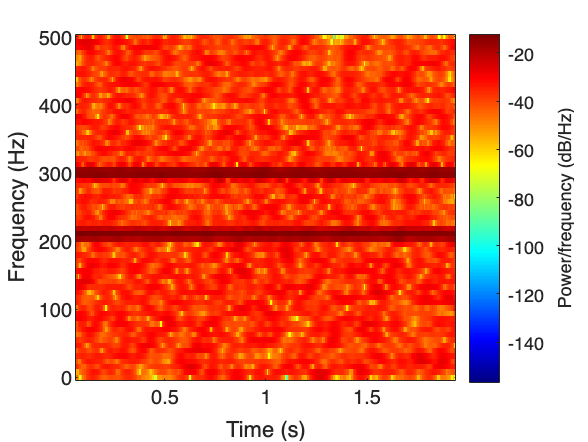

% spectrogram
spectrogram(x,128,120,128,fs,'yaxis')
colormap jet